**Variance**

Variance is the average distance squared from the mean that each point is.

Refrence: from class

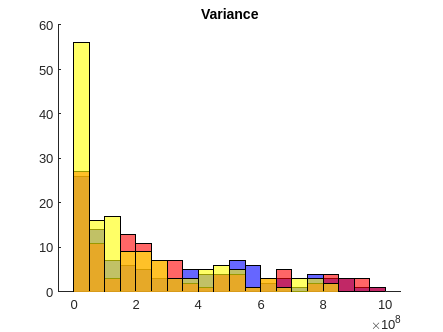

figure;
bins_for_hist = 0:5*10^7:10^9;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),1:4))', 'BinEdges', bins_for_hist, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),1:4))', 'BinEdges', bins_for_hist, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),1:4))', 'BinEdges', bins_for_hist, 'FaceColor', 'yellow') % Create the histogram
title('Variance'); %
hold off

**Mean Absolute Value**

Mean absolute value is the absolute value of every point averaged.

Refrence: https://link.springer.com/article/10.1007/s00779-019-01285-2

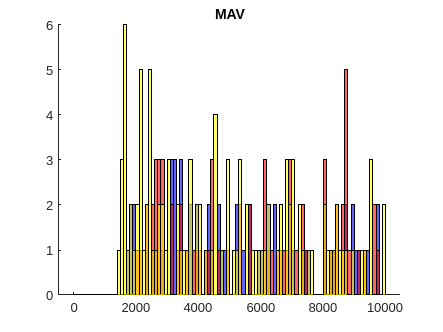

figure;
bins_for_hist_mav = 0:100:10000;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),5:8))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),5:8))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),5:8))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'yellow') % Create the histogram
title('MAV'); %
hold off

**Root mean square**

Root mean squared, is the every value squared, summed together and then has the square root taken of it.

Refrence: https://link.springer.com/article/10.1007/s00779-019-01285-2

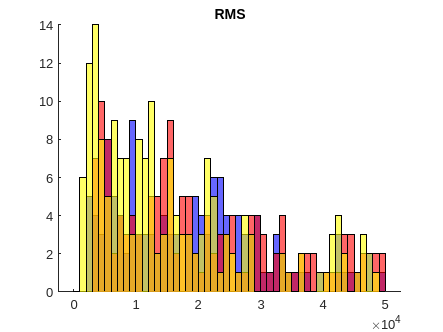

figure;
bins_for_hist_mav = 0:1000:50000;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),9:12))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),9:12))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),9:12))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'yellow') % Create the histogram
title('RMS'); %
hold off

**Waveform length**

The waveform length is the difference between each data point summed together.

Refrence: https://drive.google.com/file/d/1ksKfbenh5SuCdCPrqsODZrvLwcsU31Os/view

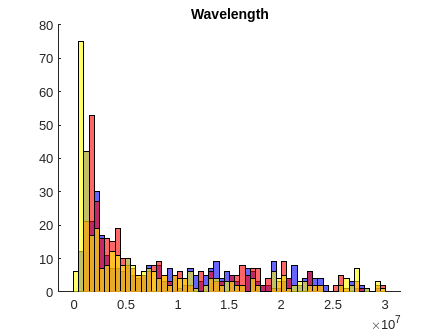

figure;
bins_for_hist_mav = 0:500000:30000000;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),13:16))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),13:16))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),13:16))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'yellow') % Create the histogram
title('Wavelength'); %
hold off

** Integrated EMG**

The iemg is the sum of every data point added together.

Refrence: https://link.springer.com/article/10.1007/s00779-019-01285-2

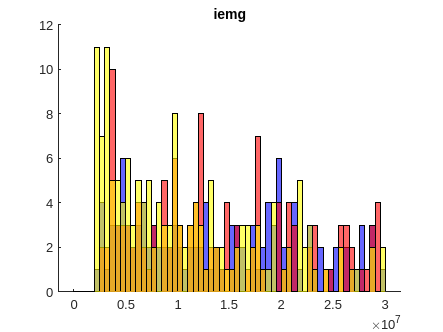

figure;
bins_for_hist_mav = 0:500000:30000000;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),17:20))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),17:20))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),17:20))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'yellow') % Create the histogram
title('iemg'); %
hold off

**Range**

The maxium is the maxium of all the data points.

Reference: Me

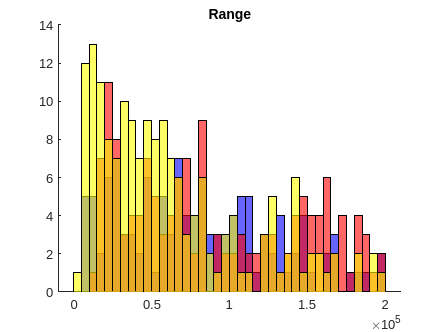

figure;
bins_for_hist_mav = 0:5000:200000;
hold on
% Plot the histogram for var
histogram(table2array(feature_table((labels==1),21:24))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'blue') % Create the histogram
histogram(table2array(feature_table((labels==2),21:24))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'red') % Create the histogram
histogram(table2array(feature_table((labels==3),21:24))', 'BinEdges', bins_for_hist_mav, 'FaceColor', 'yellow') % Create the histogram
title('Range'); %
hold off

Training Accuracies

I used K-fold cross validation to test the different feature types.

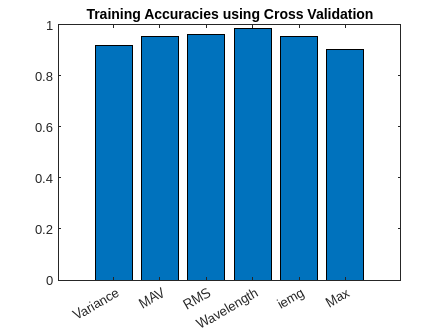

figure;
acc = [0.9185, 0.9556, 0.9630, 0.9852, 0.9556, 0.9037];
labels = {'Variance', 'MAV', 'RMS', 'Wavelength', 'iemg', 'Max'};

% Create a bar graph with labels on each bar
bar(1:numel(acc), acc);
xticks(1:numel(labels));
xticklabels(labels);

% Add a title
title('Training Accuracies using Cross Validation');

Final Model Using RMS and Wavelength

Training Data

training_conf_mat = confusionmat(y_train, y_train_predictions);

Unrecognized function or variable 'y_train'.

confusionchart(y_train, y_train_predictions)

tp = sum(diag(training_conf_mat));
tn = 0;
fn = 3;
fp = 0;
recall = tp / (tp + fn);
precision = tp / (tp + fp);
f1_score = 2 * (( precision * recall) / (precision + recall))


Testing Data

testing_conf_mat = confusionmat(y_test,y_test_predictions);
confusionchart(y_test, y_test_predictions)

precision = 1;
recall = 1;
f1_score =  2 * (( precision * recall) / (precision + recall))